# dFBA of knockout mutants

This live script runs a comets simulation trying to compare predictions with measurements with knockout-mutants on Synechocystis (Shinde et al., 2020). With the title: *Glycogen Metabolism Supports Photosynthesis Start through the Oxidative Pentose Phosphate Pathway in Cyanobacteria* 

While they use a BG11 medium (containing e.g. citrate) we continue with PRO11 medium. Because they only report OD-measurements the comparison is only qualitative.

The mutants used are:

1) glgC -> PMM0769 -> R00948

2) gnd -> PMM0770 -> R10221 and R01528

% Define simulation parameters
% In general we use conditions from Grossowicz et al. 
% Initial population in Grossowizc is 1.3e9 cells/L
grid_size = 1; %cm
grid_volume_cm3 = grid_size^3; %Cubic centimeters
grid_volume = grid_volume_cm3*1e-3; % Convert from cubic centimeters to L
cell_weight = 66*1e-15;  % g per cell (Cermak et al., 2017)
initial_pop = 1.3e9*cell_weight*grid_volume;

timeStep = 0.1;% hours
maxCycles = 240/timeStep; % Simulate 1 day
lightFlux = 0.03;
glycVmax = 0.5;
glycKm = 1e-7;
NMAX = 100; % PRO99
CO2MAX =  0.818;
model_keys = {'WT', 'glgC', 'gnd'};

% Init cobra toolbox
% initCobraToolbox;

for i=1:3
    % Load Prochlorococcus Genome-scale model
    model_fn = 'C:\Users\snorres\git\iSO595\Model_files\iSO595v5.mat';
    model = readCbModel(model_fn);
    model = setBiomassRxn(model, 'BIOMASS');
    folder = [pwd '\simulations'];
    % Set upper and lower bound of glycogen
    glycogen_index = find(strcmp(model.rxns, 'GlycogenEX'));
    model.lb(glycogen_index) = -1000;
    model.ub(glycogen_index) = 1000;
    
    CO2EX_index = find(strcmp(model.rxns, 'CO2EX'));
    model.lb(CO2EX_index) = 0;
    model.ub(CO2EX_index) = CO2MAX;
    
    % Set R06050 to forward
    %R06050_index = find(strcmp(model.rxns, 'R06050'));
    %model.lb(R06050_index) = 0;
    
    % make mutants
    if i==2
        model = deleteModelGenes(model, 'PMM0769');
    elseif i == 3
        model = deleteModelGenes(model, 'PMM0770');
    end
    
    % Define kinetic parameters
    % We use the Vmax, and Km that gives optimal
    % Use optimal Vmax and Km from Figure 3
    ammonium_Km = 0.69;
    ammonium_Vmax = 1.4;
    model = setVmax(model, 'AmmoniaEX', ammonium_Vmax);% mmol/gDW/h
    model = setKm(model, 'AmmoniaEX', ammonium_Km*1e-3);% Converting from mM to mmol/cm^3 is used in
    %model = setVmax(model, 'HCO3EXcar', 1.83);
    %model = setKm(model, 'HCO3EXcar', 0.082*1e-3);
    %model = setVmax(model, 'FAKEOrthophosphateEX', 0.7575);
    %model = setKm(model, 'FAKEOrthophosphateEX', 0.00053*1e-3);
    model = setKm(model, 'GlycogenEX', glycKm);
    model = setVmax(model, 'GlycogenEX', glycVmax);

### Define model light settings

In the following we assume that the light source is monochromatic at 680nm, however it is possible to extend the following calculations to a wave-length dependent light-source.  

It is necessary to calculate a model-specific weight-specific absorption rate, this is achieved by using  the derived pigment absorption spectra provided by Bricaud et al., 2004. The calculations follows the methods in Bricaud et al., 2004, as originally described in Morel and Bricaud, 1981. 

#### Define variables such as pigment concentrations in *Prochlorococcus, *absorption coefficients and refraction index  

At 680nm we can ignore absorption by other pigments than divinyl chlorophyll a and b.

    % The ratio of chlorophyll is extracted from the model biomass-function
    ci_dvchla = 0.028*0.581196581; % g / gDW (Partensky 1993 / Casey 2016)
    ci_dvchlb = 0.028*0.047008547; % g / gDW (Partensky 1993 / Casey 2016)
    absorption_dvchla_680 = 0.018358; % m2 mg-1 (Bricaud et al., 2004)
    absorption_dvchlb_680 = 0.0018;   % m2 mg-1 (Bricaud et al., 2004)
    absorption_water_680 = 0.465; % m^-1 (Pope and Fry, 1997)
    wavelength = 680;% nm
    diameter = 0.6; % um 
    n_dash = 13.77*1e-3; % imaginary part of refractive index at 67 nm, from Stramski et al
    %lightFlux = 0.02; % mmol Q / m^2 / s (0.02 used in Grossowicz et al., 2017)
    %lightFlux = 0.1;

#### Calculate the packaging effect

This is taking into account that the light-aborsbing pigments are not dissolved in the media, but contained with in discrete cells. See Moreail and Bricaud, 1981, for a thorough explanation. 

    % Calculate the packaging effect index Q* 
    size_parameter_alpha = diameter*1e3*pi/wavelength;
    rho_dash = 4*size_parameter_alpha*n_dash;
    Q_a = 1+(2*exp(-rho_dash)/rho_dash)+2*(exp(-rho_dash)-1)/rho_dash^2;
    packaging_effect = 1.5*Q_a/rho_dash;

#### Calculate the weight-specific absorption coefficient 

    % This coefficient is in units m^2/ g DW biomass
    % Multiply by 1e3 to convert from g to mg
    absorption_biomass = packaging_effect*(ci_dvchla*1e3*absorption_dvchla_680+ci_dvchlb*1e3*absorption_dvchlb_680);


#### Set the calculated absorption rate as a model parameter for the exchange reaction of light

    absorption_matrix = zeros(1,2);
    absorption_matrix(1) = absorption_water_680;
    absorption_matrix(2) = absorption_biomass;
    model  = setLight(model, {'LightEX'}, absorption_matrix);
    
    

### Set params

    % Define filenames
    %
    folder_i = [folder '\' model_keys{i}];
    if ~exist(folder_i,'dir')
        mkdir(folder_i);
    end
    
    fluxLogfn = sprintf('fluxLog_%d.csv',i);
    biomassLogfn = sprintf('biomassLog_%d.csv',i);
    mediaLogfn = 'mediaLog.csv';
    model.description = 'iSO595';
    layout_name = 'layout.txt';
    
    % Creat layout
    layout = CometsLayout();
    layout = layout.addModel(model);
    layout = setInitialPop(layout, '1x1', initial_pop); % g DW
    
    % Set simulation parameters
    
    layout.params.mediaLogName = [folder_i '\' mediaLogfn];
    layout.params.writeMediaLog = true;
    layout.params.mediaLogRate = 1;
    layout.params.biomassLogName = [folder_i '\' biomassLogfn];
    layout.params.writeBiomassLog = false;
    layout.params.biomassLogRate = 1;
    
    % Write fluxes
    layout.params.fluxLogName =  [folder_i '\' fluxLogfn];
    layout.params.writeFluxLog = false;
    layout.params.fluxLogRate = 1;
    
    
    layout.params.maxCycles = maxCycles;
    layout.params.timeStep = timeStep; %Hours
    layout.params.spaceWidth = grid_size; % Centimeters (0.1 is default value)
    layout.params.maxSpaceBiomass = 100000;
    layout.params.defaultDiffConst = 0;
    layout.params.objectiveStyle = 'MAX_OBJECTIVE_MIN_TOTAL';
    layout.params.deathRate = 0.1/24; % Per hour. From Grossowicz (they reference William and Follows, 2011)
    %layout.params.defaultVmax = 1000;
    %layout.params.defaultKm = 0.01;
    %put a timestep
    layout.params.useLogNameTimeStamp=false;
    layout.params.fluxLogFormat = 'COMETS';
    layout.params.mediaLogFormat = 'COMETS';
    layout.params.biomassLogFormat = 'COMETS';

### Define medium as PRO99, with modifications in Grossowicz, 2017

Defined in Moore et al., 2007. Here given in mmol whereas umol is used by Moore et al., 2007. 

PRO99 pH: 7.73 (Grossowicz, 2017) / pH Grossowicz: 7.83.

In Grossowicz, 1 mM Bicarbonate added at day 0, 5, 11, 18

    % Define medium in uM
    pro99_media = struct('ammonia', NMAX, ... % 100 Grossowizc, 800 uM in PRO99
                         'bicarbonate', 3000, ... % uM Somewhat less in PRO99
                         'phosphate', 50);
    
    % Calculate values in mmol and set to layout
    grid_volume = layout.params.spaceWidth^3*1e-3; % In cubic decimetermeter aka liters
    layout = layout.setMedia('Ammonia[e]', pro99_media.ammonia*1e-3*grid_volume); % in mmol
    layout = layout.setMedia('HCO3[e]', pro99_media.bicarbonate*1e-3*grid_volume); % in mmol
    layout = layout.setMedia('Orthophosphate[e]', pro99_media.phosphate*1e-3*grid_volume); % in mmol

## Set light conditions

    %Set  a sinus distribution of photons
    layout = layout.setGlobalPeriodicMedia('Photon[e]', "half_sin", lightFlux, 24,0,0);

### Define salts and mineral needed for growth

Set to maximum value to ensure these compounds are not limiting growth in any way

     %layout = layout.setMedia('HCO3[e]', 1000);
    %layout = layout.setMedia('CO2[e]', 1000);
    default_bound = 0.1;
    layout = layout.setMedia('H[e]', 1000);
    %layout = layout.setMedia('Orthophosphate[e]', default_bound); 
    layout = layout.setMedia('H2O[e]', 1000);
    layout = layout.setMedia('Oxygen[e]', 0.1);
    %layout = layout.setMedia('Ammonia[e]', 1000);
    
    layout = layout.setMedia('Cadmium[e]', default_bound);
    layout = layout.setMedia('Calcium_cation[e]', default_bound);
    layout = layout.setMedia('Chloride_ion[e]', default_bound);
    layout = layout.setMedia('Cobalt_ion[e]', default_bound);
    layout = layout.setMedia('Copper[e]', default_bound);
    
    layout = layout.setMedia('Fe2[e]', default_bound);
    layout = layout.setMedia('Magnesium_cation[e]', default_bound);
    layout = layout.setMedia('Molybdenum[e]', default_bound);
    layout = layout.setMedia('K[e]', default_bound);
    layout = layout.setMedia('Selenate[e]', default_bound);
    layout = layout.setMedia('Sodium_cation[e]', default_bound);
    layout = layout.setMedia('Strontium_cation[e]', default_bound);
    layout = layout.setMedia('Sulfate[e]', 0.0312);
    layout = layout.setMedia('Zn2[e]', default_bound);
    layout = layout.setMedia('Glycogen[e]', 0.0000);
    %layout = layout.setMedia('Hydrogen_sulfide[e]',1000);
    
    
    

### Set multilevel objective to ensure glycogen production

    photonUptakeIndex = find(strcmp(layout.models{1,1}.rxns, 'LightEX'));
    biomassIndex = find(strcmp(layout.models{1,1}.rxns, 'BIOMASS'));
    hco3_index = find(strcmp(layout.models{1,1}.rxns, 'HCO3EXcar'));
    glycogen_index = find(strcmp(layout.models{1,1}.rxns, 'GlycogenEX'));
    ATPM_index = find(strcmp(layout.models{1,1}.rxns, 'Maintenance'));
    %layout.models{1,1}.c(photonUptakeIndex) = 1;
    
    layout.models{1,1}.c(ATPM_index) = 1;
    layout.models{1,1}.lb(ATPM_index) = 0;
    layout.models{1,1}.c(photonUptakeIndex) = -2;
    layout.models{1,1}.c(biomassIndex) = 3;
    %layout.models{1,1}.c(hco3_index) = -4;
    layout.models{1,1}.c(glycogen_index) = 4;
    
    % Write layout
    createCometsFiles(layout, folder_i, layout_name);
    

end

for i=1:3
   folder_i = [folder '\' model_keys{i}];
   % run comets
   runCometsOnDirectory(folder_i)
   cd('../..'); 
end

ans =     '
     C:\Users\snorres\OneDrive - SINTEF\Boston University\Marine strains project\Modelling\Prochlorococcus\knockout_diurnal_data_comparison\simulations\WT>java -Xmx2048m -classpath C:\Users\snorres\cometsS/comets.jar;C:\Users\snorres\cometsS/bin/comets.jar;C:\Users\snorres\cometsS/lib/glpk-java.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jmatio.jar;C:\Users\snorres\cometsS/lib/jamtio.jar;C:\gurobi811\win64/lib/gurobi.jar -Djava.library.path=C:\Users\snorres\cometsS/;C:\Users\snorres\cometsS/lib/;C:\gurobi811\win64/lib/;C:\gurobi811\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBAC

ans =     '
     C:\Users\snorres\OneDrive - SINTEF\Boston University\Marine strains project\Modelling\Prochlorococcus\knockout_diurnal_data_comparison\simulations\glgC>java -Xmx2048m -classpath C:\Users\snorres\cometsS/comets.jar;C:\Users\snorres\cometsS/bin/comets.jar;C:\Users\snorres\cometsS/lib/glpk-java.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jmatio.jar;C:\Users\snorres\cometsS/lib/jamtio.jar;C:\gurobi811\win64/lib/gurobi.jar -Djava.library.path=C:\Users\snorres\cometsS/;C:\Users\snorres\cometsS/lib/;C:\gurobi811\win64/lib/;C:\gurobi811\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FB

ans =     '
     C:\Users\snorres\OneDrive - SINTEF\Boston University\Marine strains project\Modelling\Prochlorococcus\knockout_diurnal_data_comparison\simulations\gnd>java -Xmx2048m -classpath C:\Users\snorres\cometsS/comets.jar;C:\Users\snorres\cometsS/bin/comets.jar;C:\Users\snorres\cometsS/lib/glpk-java.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\Users\snorres\cometsS/lib/jmatio.jar;C:\Users\snorres\cometsS/lib/jamtio.jar;C:\gurobi811\win64/lib/gurobi.jar -Djava.library.path=C:\Users\snorres\cometsS/;C:\Users\snorres\cometsS/lib/;C:\gurobi811\win64/lib/;C:\gurobi811\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBA

## Plot results

% Load experimental data
%hold on;

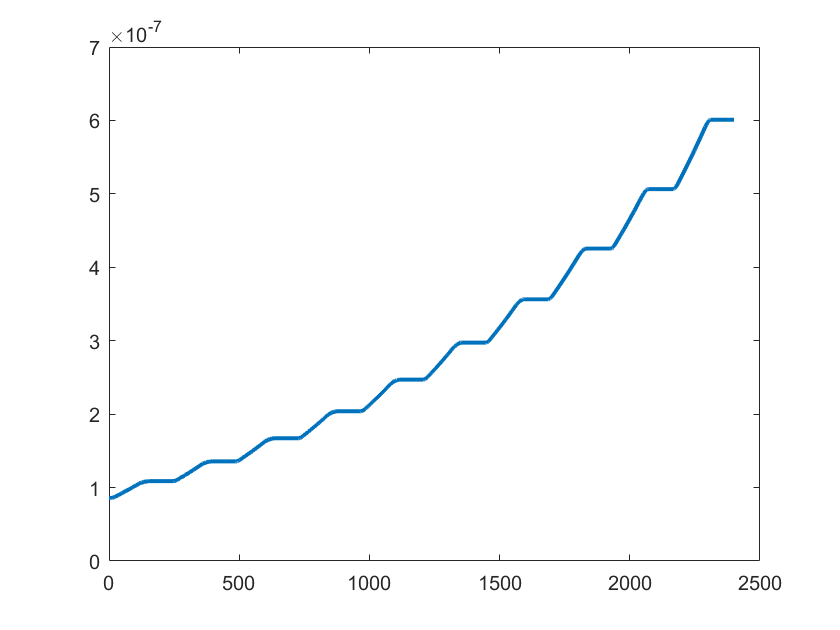

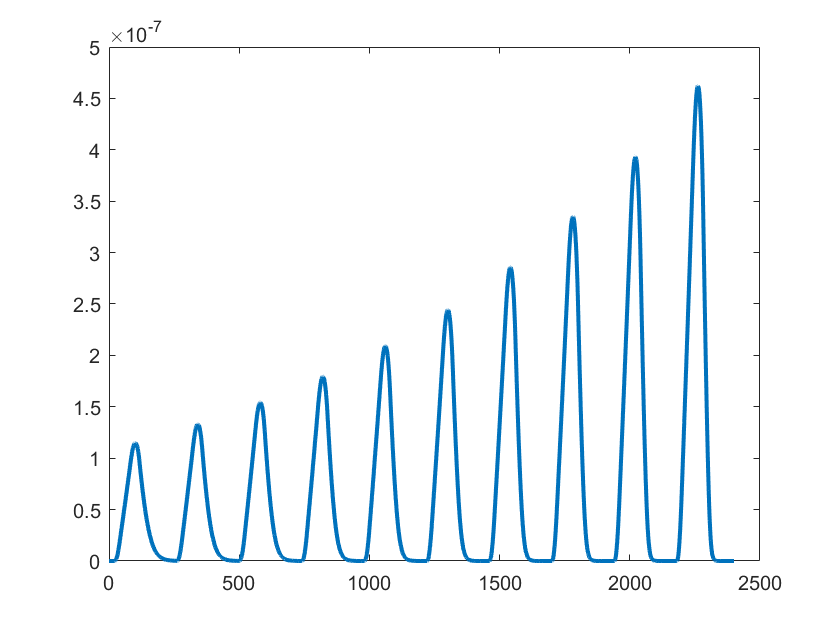

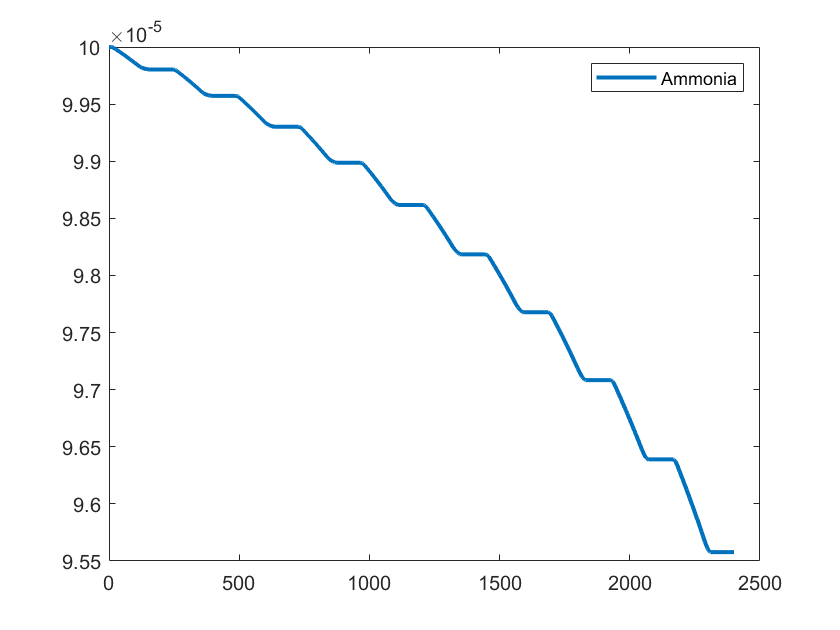

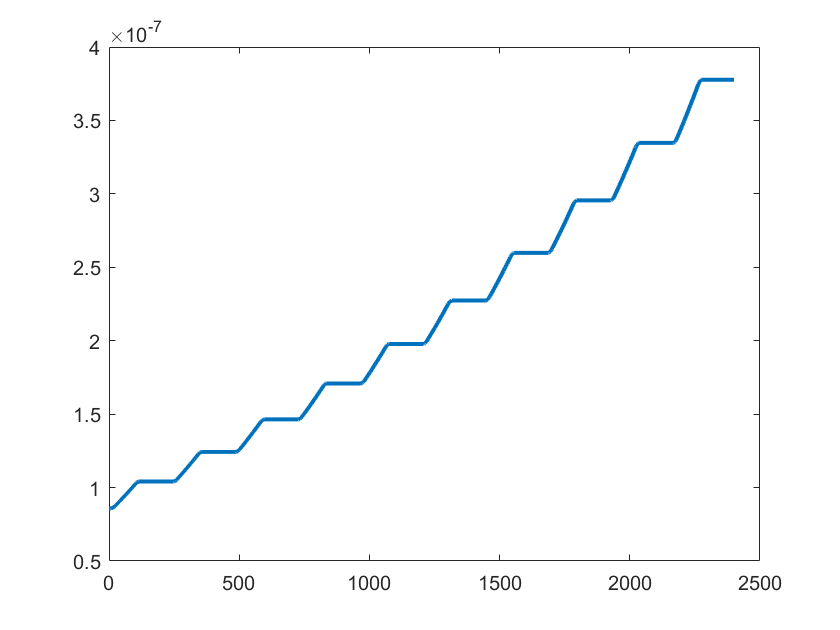

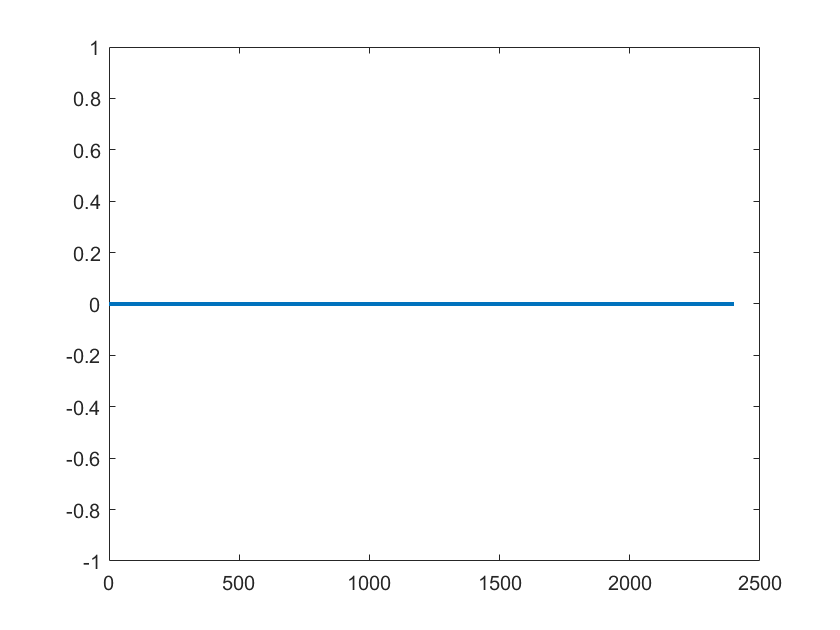

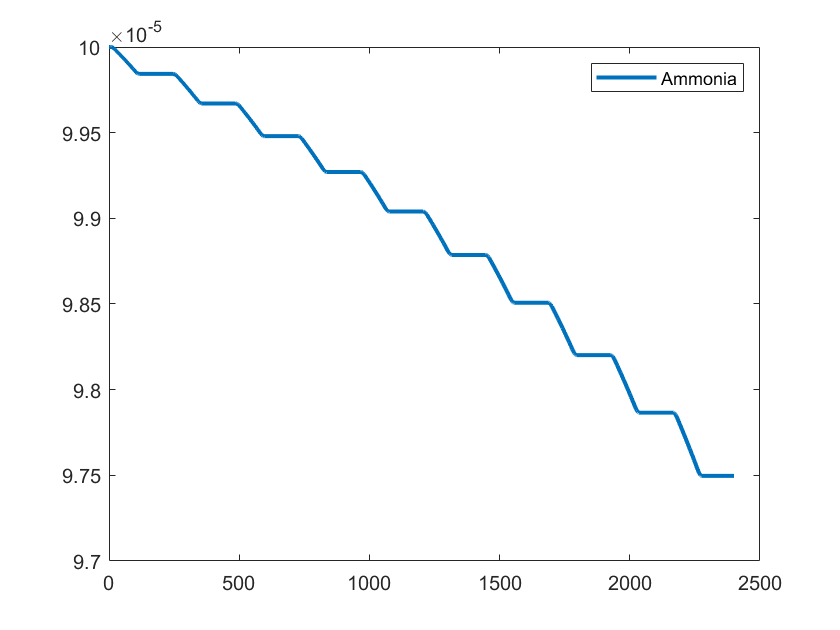

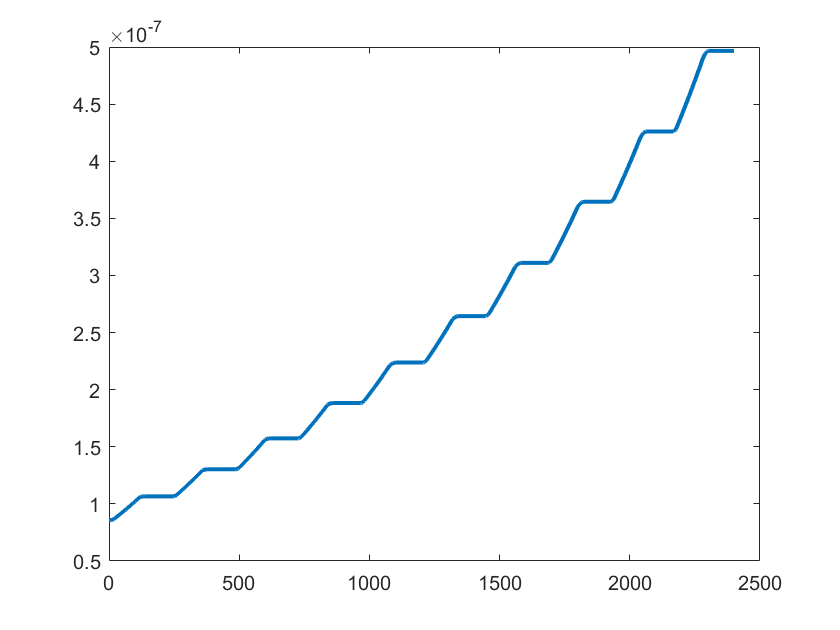

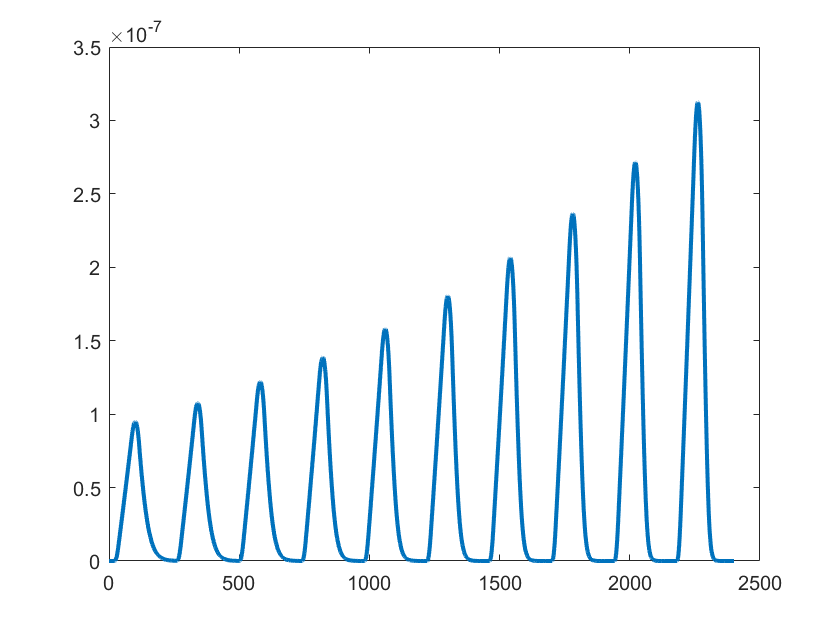

for i=1:3
    folder_i = [folder '\' model_keys{i}];
    media = parseMediaLog([folder_i '\' mediaLogfn]);
    
    %converting from biomass (g DW) to number of cells
    f = figure();
    biomass_table = media(strcmp('biomass[e]', media.metname),:);
    plot(biomass_table.t, biomass_table.amt+initial_pop, 'DisplayName', 'Predicted growth', 'LineWidth',2);
    saveas(f, [folder_i '\Growth.png'])
    f = figure();
    glycogen = media(strcmp('Glycogen[e]', media.metname),:);
    plot(glycogen.t, glycogen.amt, 'DisplayName', 'Glycogen', 'LineWidth',2);
    saveas(f, [folder_i '\Glycogen.png'])
    
    f = figure();
    photon = media(strcmp('Photon[e]', media.metname),:);
    plot(photon.t, photon.amt, 'DisplayName', 'Photon', 'LineWidth',2);
    saveas(f, [folder_i '\Light.png'])
    Ammonia = media(strcmp('Ammonia[e]', media.metname),:);
    plot(Ammonia.t, Ammonia.amt, 'DisplayName', 'Ammonia', 'LineWidth',2);
    legend()
    %hold on;
    
    results_table = table(biomass_table.t*timeStep, biomass_table.amt+initial_pop,glycogen.amt,photon.amt, 'VariableNames', {'Time','Biomass','Glycogen', 'Photon'});
    writetable(results_table, [folder_i '\' 'results_table.csv'])
    
    %fluxLogfn = sprintf('fluxLog_%d.csv',i);
    %flux = parseFluxLog([folder_i '\' fluxLogfn]);
    
    writecell(layout.models{1,1}.rxns, [folder_i '\' 'rxnIDs.csv']);
    %writetable(flux, [folder_i '\' 'fluxTable.csv'])
    writetable(media, [folder_i '\' 'mediaTable.csv'])
end